N = 100000

N = 100000

numbers = rand(1, N)

numbers =     0.2265    0.4692    0.3432    0.3067    0.8714    0.5310    0.0727    0.9250    0.7448    0.3062    0.6120    0.6227    0.6752    0.0597    0.8816    0.7891    0.6680    0.9811    0.7165    0.0493    0.7782    0.0489    0.4758    0.4290    0.5846    0.3620    0.2119    0.8143    0.8354    0.5599    0.1093    0.6103    0.6352    0.2175    0.3832    0.5916    0.7344    0.1863    0.1799    0.3618    0.6346    0.5087    0.0339    0.9112    0.4291    0.0491    0.2061    0.2530    0.8408    0.7193


numbers2 = fast_rand_eca(1, N)

columns_to_sample =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


numbers2 =     0.4161    0.9926    0.6193    0.5723    0.0363    0.3885    0.5289    0.1936    0.1194    0.0132    0.7065    0.7664    0.4619    0.2888    0.8685    0.1927    0.3521    0.9020    0.5568    0.2152    0.9426    0.2224    0.7240    0.6511    0.2761    0.0118    0.3431    0.2402    0.1158    0.0959    0.6848    0.2723    0.8848    0.4065    0.1510    0.9324    0.5229    0.4031    0.2714    0.7621    0.3669    0.9678    0.6310    0.3408    0.5912    0.1631    0.9938    0.4546    0.1958    0.1334



num_bins = 20;
bin_edges = (0:num_bins) ./ num_bins

bin_edges =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000



function bin_loc = find_bin(bin_edges, number)
    for i = 1:(length(bin_edges)-1)
        % number fit within [bin_edge, bin_edge)
        if ( number >= bin_edges(i) ) && ( number < bin_edges(i+1) ) 
            bin_loc = i;
            break;
        end
    end
end

function counts = count_bins(bin_edges, data)
    counts = zeros(1, length(bin_edges) - 1);
    for i=1:length(data)
        bin_loc = find_bin(bin_edges, data(i));
        counts(bin_loc) = counts(bin_loc) + 1;
    end
end

counts = count_bins(bin_edges, numbers)

counts =         4975        4990        5008        4943        5030        5031        5021        5013        4917        5018        5019        4992        4994        4979        4892        5106        5001        5003        5100        4968


counts2 = count_bins(bin_edges, numbers2)

counts2 =         4935        4944        4978        5037        4905        5007        4914        4914        4868        5057        5139        4997        5174        5094        5008        5039        4956        4945        5046        5043


Then I want to see how the observed compares to the actual

What is an actual? For each bin, there would be equal likely hood of finding.

function error = normalize_for_chi_sqaured(counts, N)
    num_bins = length(counts);
    uniform_per_bin_count = N / num_bins;
    true_uniform = zeros(1, num_bins) + uniform_per_bin_count; 
    error = sum( (counts - true_uniform).^2 ./ true_uniform );
end
normalize_for_chi_sqaured(counts, N)

ans = 9.7116

then we can plot what the best would have looked like

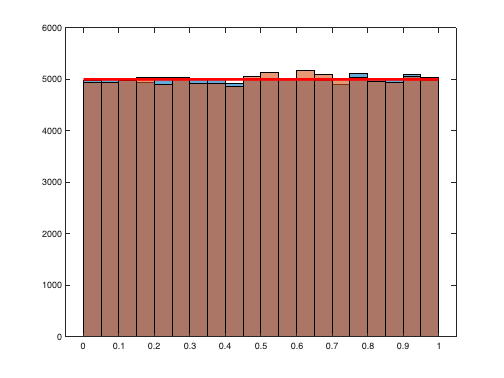

histogram(numbers, bin_edges)
hold on
histogram(numbers2, bin_edges)
hold on
plot([0 1], zeros(1, 2) + N / num_bins, "r-", "LineWidth", 3)
hold off

h_0 is that rand() is a uniform distrbution for n bins

b_1 unequal fruencies and not random uniform

alpha of 0.05 means that we reject h_0 5% of the time, when we should have failed to reject it.

num_bins = 20;
CRV = chi2inv(0.95, num_bins-1) % Critiical value for alpha=0.95 for df=15

CRV = 30.1435

bin_edges = (0:num_bins) ./ num_bins;
max_val = 100000;
Ns = ceil(linspace(32, max_val, 1000));
rand1 = rand(1, max_val);
rand2 = fast_rand_eca(1, max_val);

columns_to_sample =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


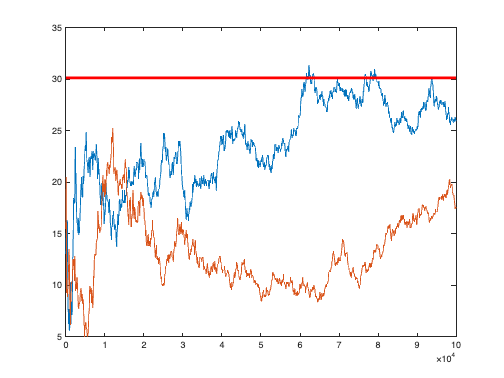

outputs = zeros(1, length(Ns));
outputs2 = zeros(1, length(Ns));
for i=1:length(Ns)
    N_i = Ns(i);
    numbers_i = rand1(1:N_i);
    numbers2_i = rand2(1:N_i);

    counts_i = count_bins(bin_edges, numbers_i);
    counts2_i = count_bins(bin_edges, numbers2_i);

    outputs(i) = normalize_for_chi_sqaured(counts_i, N_i);
    outputs2(i) = normalize_for_chi_sqaured(counts2_i, N_i);
end
plot(Ns, outputs)
hold on
plot(Ns, outputs2)
hold on
plot([Ns(1) Ns(end)], zeros(1, 2) + CRV, "r-", "LineWidth", 3)
hold off